# Exam 2

Kathryn Atherton

03/08/2019

ABE 30100

## Problem A

### Part 1

Create a cubic spline model for velocity as a funciton of radial position. Provide an appropriate plot.

% Input Data
r = [0, 1, 2, 3, 4, 5, 6]; % radius, independent variable, [inches]
v = [15, 14.58, 13.33, 11.25, 8.33, 4.58, 0]; % velocity, dependent variable, % [inches/s]

S = cubic_spline(r, v);

Valid from x = 0.0000 to 1.0000

$$f = -0.17577\,x^{3}-0.24423\,x+15.0$$

Valid from x = 1.0000 to 2.0000

$$f = 0.048846\,{\left(x-1.0\right)}^{3}-0.52731\,{\left(x-1.0\right)}^{2}-0.77154\,x+15.352$$

Valid from x = 2.0000 to 3.0000

$$f = 16.689-0.38077\,{\left(x-2.0\right)}^{2}-0.019615\,{\left(x-2.0\right)}^{3}-1.6796\,x$$

Valid from x = 3.0000 to 4.0000

$$f = 0.019615\,{\left(x-3.0\right)}^{3}-0.43962\,{\left(x-3.0\right)}^{2}-2.5\,x+18.75$$

Valid from x = 4.0000 to 5.0000

$$f = 21.612-0.38077\,{\left(x-4.0\right)}^{2}-0.048846\,{\left(x-4.0\right)}^{3}-3.3204\,x$$

Valid from x = 5.0000 to 6.0000

$$f = 0.17577\,{\left(x-5.0\right)}^{3}-0.52731\,{\left(x-5.0\right)}^{2}-4.2285\,x+25.722$$

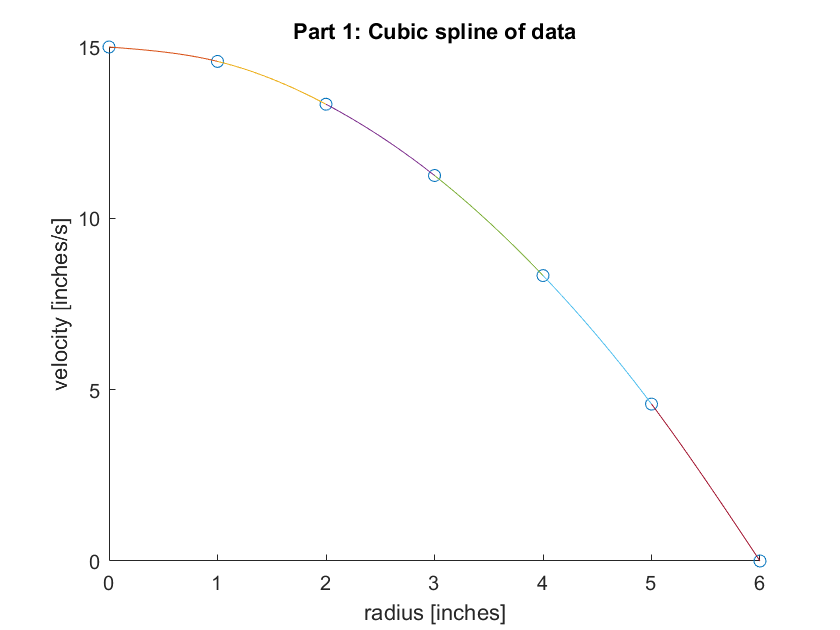

title('Part 1: Cubic spline of data')
xlabel('radius [inches]')
ylabel('velocity [inches/s]')

### Part 2

Calculate the value of the fluid viscosity, mu, and prove that this is a Newtonian fluid.

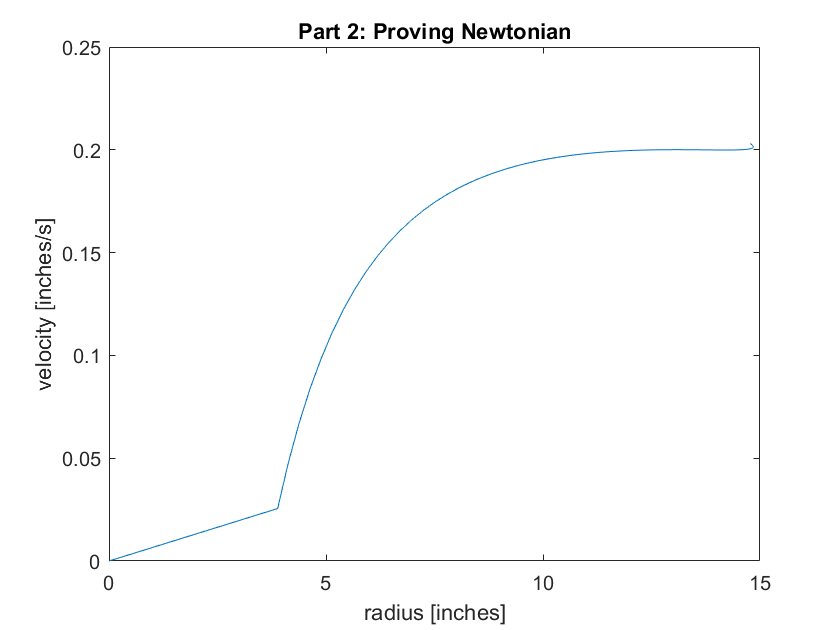

r = 0:0.1:6; % radius, [inches]
mu = zeros(length(r),1); % viscosity, [lbm/in-s]
vr = zeros(length(r),1); % velocity, [inches/s]
delP = 40; % pressure, [lbf/in^2]
r_total = 6; % total radius of the pipe, [inches]
L = 120; % length, [inches]
i = 1; % counter

while r(i) < r_total
    if x < 1
        vr(i) = -0.17577 * r(i)^3 - 0.24423 * r(i) + 15;
        mu(i) = delP * (r_total ^ 2 - r(i) ^ 2) / (4 * vr(i) * L);
    elseif x < 2
        vr(i) = 0.048846 * (r(i) - 1) ^ 3 - 0.52731 * (r(i) - 1) ^ 2 - 0.77154 * r(i) + 15.352;
        mu(i) = delP * (r_total ^ 2 - r(i) ^ 2) / (4 * vr(i) * L);
    elseif x < 3
        vr(i) = 16.689 - 0.38077 * (r(i) - 2) ^ 2 - 0.019615 * (r(i) - 2) ^ 3 - 1.6796 * r(i);
        mu(i) = delP * (r_total ^ 2 - r(i) ^ 2) / (4 * vr(i) * L);
    elseif x < 4
        vr(i) = 0.019615 * (r(i) - 3) ^ 3 - 0.43962 * (r(i) - 3) ^ 2 - 2.5 * r(i) + 18.75;
        mu(i) = delP * (r_total ^ 2 - r(i) ^ 2) / (4 * vr(i) * L);
    elseif x < 5
        vr(i) = 21.612 - 0.38077 * (r(i) - 4) ^ 2 - 0.048846 * (r(i) - 4) ^ 3 - 3.3204 * r(i);
        mu(i) = delP * (r_total ^ 2 - r(i) ^ 2) / (4 * vr(i) * L);
    else 
        vr(i) = 0.17577 * (r(i) - 5) ^ 3 - 0.52731 * (r(i) - 5) ^ 2 - 4.2285 * r(i) + 25.722;
        mu(i) = delP * (r_total ^ 2 - r(i) ^ 2) / (4 * vr(i) * L);
    end
    i = i + 1; % adds to counter to continue while loop
end
figure
plot(vr,mu)
title('Part 2: Proving Newtonian')
xlabel('radius [inches]')
ylabel('velocity [inches/s]')

### Part 3

Calculate the flowrate, Q. 

Q = pi * delP * r_total ^ 4 / (8 * mean(mu) * L) % flowrate, [in^3/s]

Q = 968.3916

## Problem B

V = 100; % volume, [L]
q = 5; % [L/h]
CA0 = 100; % [mol/L]
vm1 = 3.3; % [mol/L-h]
km1 = 0.05; % [mol/L-h]
vm2 = 5; % [mol/L-h]
km2 = 200; % [mol/L-h]

syms C
f = q * CA0 - q * C - (vm1 * C / (km1 + C) + vm2 * C / (km2 + C)) * V;

[x_root, i] = newton_raphson(f, CA0, 0.001);
x_root

x_root = 23.5893

V = 150; % volume, [L]

syms C
f = q * CA0 - q * C - (vm1 * C / (km1 + C) + vm2 * C / (km2 + C)) * V;

[x_root, i] = newton_raphson(f, CA0, 0.001);
x_root

x_root = -1.4477

## Functions

### Root-Finding Functions

function [x_root, i] = newton_raphson(f, x1, error_tol)
    C      = x1;
    zero   = double(subs(f));                                  % sets zero to the value of the 
                                                                   % function at the given x 
                                                                   % point
    x_root = x1;                                               % renames input x value
    i      = 0;                                                % sets iteration counter to zero 
    while abs(zero) > error_tol                                % checks to see if another 
                                                                   % iteration should be 
                                                                   % performed
        C     = x_root;
        slope = double(subs(diff(f)));                         % finds the slope of the function 
                                                                   % at the given point
        if slope == 0                                          % checks for a minimum or maximum
            fprintf('Error: stuck at minimum or maximum of function.\n')
            zero   = 0;                                        % breaks the while loop so that the 
                                                                   % function doesn't go on forever
            x_root = 'N/A'; 
        else
            b      = zero - slope * x_root;                    % finds the b of the function 
                                                                   % y = mx + b
            x_root = double(-b / slope);                       % finds the new x where y = 0 for 
                                                                   % the linear function
            C      = x_root;
            zero   = double(subs(f));                          % finds the value of the function 
                                                                   % at the x found above
            i      = i + 1;                                    % adds iteration to counter
        end
    end
    if x_root == 'N/A'                                         % changes the zero value to N/A in 
                                                                   % the case that a maximum was 
                                                                   % found after loop break
        zero  = 'N/A';
    end
end 

### Cubic Spline Functions

function S = cubic_spline(x1, y)
m = length(x1);                                                % finds the length of the x vector
n = length(y);                                                 % finds the length of the y vector

if m ~= n                                                      % checks that x and y are the same 
                                                                   % length
    error('Error: x and y have different dimensions.');
elseif m < 3                                                   % checks that there are more than 3 
                                                                   % points
    error('Error: not enough points to create a cubic spline.');
else
    scatter(x1,y);                                             % plots the data as a scatter plot
    hold on;
    [A, B, C, D] = spline_coeff(x1,y);                         % calls the spline coefficient-making 
                                                                   % function
    S = zeros(m, 1);                                           % makes a vector of zeros to hold the 
                                                                   % spline functions
    for i = 1:m-1                                              % iterates through the spline 
                                                                   % functions (one less than the 
                                                                   % number of points)
        a = double(A(i));                                      % assigns a variable to the A coefficient
        b = double(B(i));                                      % assigns a variable to the B coefficient
        c = double(C(i));                                      % assigns a variable to the C coefficient
        d = double(D(i));                                      % assigns a variable to the D coefficient
        digits(5)                                              % assigns the number of significant figures 
                                                                   % displayed when the functions are 
                                                                   % printed
        syms x                                                 % assigns x to be a symbolic variable
        fprintf('Valid from x = %.4f to %.4f', x1(i), x1(i + 1))
                                                               % prints the calculated spline function and 
                                                                   % its valid range
        f = vpa(a) + (vpa(b) * (x - vpa(x1(i)))) + (vpa(c) * ((x - vpa(x1(i))) ^ 2)) + ...
            (vpa(d) * ((x - vpa(x1(i))) ^ 3))
        vals = x1(i):0.01:x1(i+1);                             % makes an array of x values in the valid 
                                                                   % range
        x = vals;                                           
        plot(vals, subs(f));                                   % plots the calculated spline function
        hold on;
    end
end
end

function H = h_matrix(x)
n = length(x);                                                 % finds the length of the x vector 
H = zeros(n,n);                                                % creates a square vector with dimensions 
                                                                   % the size of the x vector
H(1,1) = 1;                                                    % assigns the first and last element along 
                                                                   % the diagonal to be 1
H(n,n) = 1;
for i = 2:n-1                                                  % iterates through the rest of the rows
    for j = 1:n                                                % iterates through the columns
        if j == i                                              % finds the element on the diagonal and 
                                                                   % assigns the elements on and before 
                                                                   % and after the appropriate H-matrix 
                                                                   % functions
            H(i, j) = double(2 * ((x(i) - x(i - 1)) + (x(i + 1) - x(i))));
            H(i, j - 1) = double(x(i) - x(i - 1));
            H(i, j + 1) = double(x(i + 1) - x(i));
        end
    end
end
end

function C = k_matrix(x, y)
m = length(x);                                                 % finds the length of the x vector
n = length(y);                                                 % finds the length of the y vector
if m ~= n                                                      % checks that x and y have the same length
    error("Error: x and y have different dimensions.");
else
    K = zeros(m,1);                                            % makes a vector of zeros of the size of x
    for i = 2:m-1                                              % iterates through the middle elements (not 
                                                                   % the first and last) and calculates
                                                                   % the appropriate variables (a and h)
        h1 = double(x(i + 1) - x(i));
        h0 = double(x(i) - x(i - 1));
        a2 = double(y(i + 1));
        a1 = double(y(i));
        a0 = double(y(i - 1));
                                                               % calculates the K-function
        K(i,1) = double(((3 * (a2 - a1)) / h1) - ((3 * (a1 - a0)) / h0)); 
    end
    H = h_matrix(x);                                           % calls the H matrix function
    C = H\K;                                                   % obtains the C coefficients by dividing 
                                                                   % the H matrix by the K vector
end
end

function [A, B, C, D] = spline_coeff(x, y)
m = length(x);                                                 % finds the length of x
n = length(y);                                                 % finds the length of y
if m ~= n                                                      % checks that x and y are the same size
    error('Error: x and y have different dimensions.');
else
    B = zeros(length(y)-1,1);                                  % makes an appropriately sized B coefficient 
                                                                   % vector
    D = B;                                                     % makes an appropriately sized D coefficient 
                                                                   % vector
    C = k_matrix(x,y);                                         % calls the K matrix function to find the C 
                                                                   % coefficients
    A = y;                                                     % assigns the y values to the A coefficients
    for i = 1:m-1                                              % iterates through the lengths of the B and 
                                                                   % D vectors and finds the B and D 
                                                                   % coefficients from A, C, and the calculated 
                                                                   % h variable
        h = (x(i + 1) - x(i));
        B(i,1) = double(((A(i + 1) - A(i)) / h) - (((C(i + 1) + 2 * C(i)) * h) / 3));
        D(i,1) = double((C(i + 1) - C(i)) / (3 * h));
    end
end
end